

m = 0;
%Domain length
L=0.5;
%Standard deviation of the noise
sigma=1;

mu=5;
gamma_A = 0.35;  

g_A = 8;


x_divs=400;
x = linspace(0,0.5,x_divs); % space
t_divs=10000;
t_max=10000;
t = linspace(1,t_max,t_divs); % time
A=100; B=10; C=0.5;
sol = pdepe(m,@pde_fn_pde,@pde_fn_ic,@pde_fn_bc,x,t,[],A,B,C);
u1 = sol(:,:,1);
u2 = sol(:,:,2);
%The plotting stuff

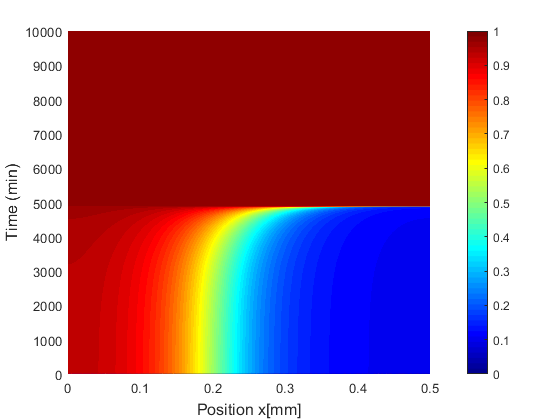


c=u1 ;
surf(x,t,u1/(g_A/gamma_A)), colormap jet,shading interp,caxis([0,1]), 
view([0.4 90.0])
colorbar
xlabel('Position x[mm]',"FontSize",12,"FontName",'Arial','FontWeight','bold');
ylabel('Time (min)',"FontSize",12,"FontName",'Arial','FontWeight','bold');

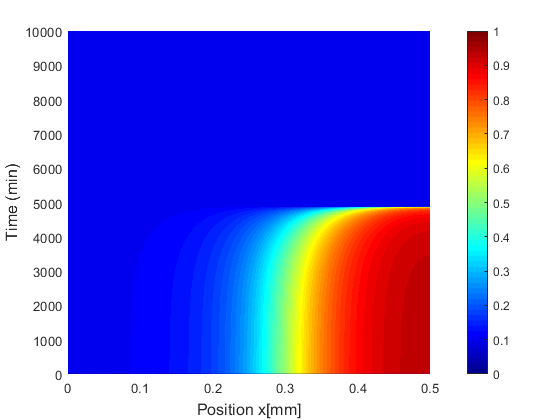


surf(x,t,u2/(g_A/gamma_A)), colormap jet,shading interp,caxis([0,1]), 
view([0.4 90.0])
colorbar
xlabel('Position x[mm]',"FontSize",12,"FontName",'Arial','FontWeight','bold');
ylabel('Time (min)',"FontSize",12,"FontName",'Arial','FontWeight','bold');

%title('Colorbar showing level of A [nM]')

function [c,f,s] = pde_fn_pde(x,t,u,DuDx,A,B,C)
c = [1; 1]; % c diagonal terms

f = [0.001; 0.001] .* DuDx; % diffusion term
% D_b=0.000005;
% D_a=0.000001*sin(20*x)^2 + 0.000001;
%  f = [0.0001; 0.0001] .* DuDx; % diffusion term
%f = [D_a; D_b] .* DuDx; % diffusion term
s=interactions(t,u);
end

function [pl,ql,pr,qr] = pde_fn_bc(xl,ul,xr,ur,t,A,B,C)
pl = [0; 0];
ql = [1; 1];
pr = [0; 0];
qr = [1; 1];
end

function u0 = pde_fn_ic (x,A,B,C)
global mu % mu tells us how quickly and how much the concentraion decays
mu=5 ;

global L
L=0.5; % The Domain length L is defined in this line

u0 = [3+A*exp(-((x)*mu))+25*normrnd(0,1,size(x))
    3+A*exp(-((L-x)*mu))+25*normrnd(0,1,size(x))];
end



We define a function that returns the time taken to reach the steady state by the system

function t=time_for_ss(sol,x_divs,t_divs,t_max)
%This function expects a 2-D array of x and t axis
%We would be using two for loops

n=x_divs;
for i=1:t_divs
    curr_max=sol(i,1);
    curr_min=sol(i,1);
    for j=1:n
        
        if curr_min>sol(i,j)
            
            curr_min=sol(i,j);
            
        end
        
        if curr_max< sol(i,n-j+1)
            
            curr_max=sol(i,j);
            
        end
        
        if abs(curr_max-curr_min) > 0.01
            break;
           
        end
        
        
    end
    if abs(curr_max-curr_min)<0.01
        t=i*t_max/t_divs ;
        break;
    end
   
    
end
end


% hill function
function H = hill(X,X0,lambda,n)
% H+ 
H1 = (X^n)/(X0^n+X^n);
% H-
H2 = (X0^n)/(X0^n+X^n);

% Hill function =  H- plus (lambda)* H+
H = H2 + lambda*H1;

end


function dxdt = interactions(t,x)

% defining array of values for the time t: 
dxdt = zeros(2,1);
g=10;
A0B_scale=10;

g_B = 10;   
B0A = 10;
g_divs=10;
g_array=linspace(0.7*g,1.3*g,g_divs);
A0B_divs=15;
A0B_array=linspace(0.7*A0B_scale,1.4*A0B_scale,A0B_divs);
g_A=g_array(8);
A0B=A0B_array(4);
%% Paramaters
% Degradation rate:
gamma_A = 0.35;   gamma_B = 0.35;  

% Transcription rate/ Production rate:
g_A =8; 
g_B = 8;   

% Hills function threshold :
A0B = 4;
B0A = 4;
A0A = 10;   B0B = 10;

% Cooperativity/ hill function coefficient:
nAtoB = 6;   nBtoA = 6;
nAtoA = 3;   nBtoB = 3;

% fold change/ lambda
lambda_AtoB = 0.1;   lambda_BtoA = 0.1;
lambda_AtoA = 3;   lambda_BtoB = 3;

% equations:
dxdt(1) = g_A*hill(x(2),B0A,lambda_BtoA,nBtoA) - gamma_A*x(1) ;  %% equation A
dxdt(2) = g_B*hill(x(1),A0B,lambda_AtoB,nAtoB) - gamma_B*x(2) ; % equation B
end

% % 
% dxdt(1) = g_A*hill(x(1),A0A,lambda_AtoA,nAtoA)*hill(x(2),B0A,lambda_BtoA,nBtoA) - gamma_A*x(1) ;  %% equation A
% dxdt(2) = g_B*hill(x(2),B0B,lambda_BtoB,nBtoB)*hill(x(1),A0B,lambda_AtoB,nAtoB) - gamma_B*x(2) ; % equation B
% end



